# PARAFAC tutorial

**Notice:** This is a tutorial on how to PARAFAC with the toolbox. For an in-depth discussion on valid models, please refer to [Murphy et al. (2013)](https://pubs.rsc.org/en/content/articlehtml/2013/ay/c3ay41160e). The models produced in this tutorial might not satisfy all criteria of validity and are simply intended to demonstrate procedures and toolbox functionality.

## Toolbox setup and initiation

clearvars
close all force
cd(fileparts(matlab.desktop.editor.getActiveFilename))
tbx=drEEMtoolbox;
load("tutorial_01_processed.mat")

## Hold up! How does your data look?

Ready, right? Not quite! There's a simple rule that applies in computer science: [GIGO, or garbage in, garbage out](https://en.wikipedia.org/wiki/Garbage_in,_garbage_out). We can't expect a representation of our data to look reasonable if the algorithm is fed unreasonable data. We need to take a look at the data first if we have not done so already.

tbx.viewabsorbance(samples)
tbx.vieweems(samples)

Also, is the dataset ready for PARAFAC?

disp(samples.status)

  drEEMstatus with properties:

    spectralCorrection: 'applied by instrument software'
         IFEcorrection: "applied by toolbox"
      blankSubtraction: "applied by toolbox"
     signalCalibration: "applied by toolbox (RU)"
      scatterTreatment: "applied by toolbox"
         signalScaling: 'original scale'
        absorbanceUnit: 'absorbance per cm'



For example, the fluoresccence signals should be calibrated in some way (the toolbox supports Raman Units). Scatter should be removed. Good news is that the toolbox actually checks for you!

After you browsed through the data above and agree that the samples look reasonable, we can proceed to fit the first models.

## Preliminary test models & dataset refinement

samples=tbx.fitparafac(samples,f=2:7,convergence=1e-4,starts=2);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6  7]
Number of random starts:         2
Convergence criterion:           0.0001
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.749
-----
  
# 001 done | #iter: 14   | time: 00:03 | it/sec: 5
# 002 done | #iter: 23   | time: 00:03 | it/sec: 9
# 003 done | #iter: 27   | time: 00:03 | it/sec: 9
# 004 done | #iter: 26   | time: 00:03 | it/sec: 9
# 005 done | #iter: 175  | time: 00:05 | it/sec: 44
# 006 done | #iter: 116  | time: 00:04 | it/sec: 32
# 007 done | #iter: 48   | time: 00:04 | it/sec: 13
# 008 done | #iter: 321  | time: 00:05 | it/sec: 68
# 009 done | #iter: 170  | time: 00:03 | it/sec: 67
# 010 done | #iter: 42   | time: 00:02 | it/sec: 23
# 011 done | #iter: 296

tbx.viewmodels(samples)
samples=tbx.addcomment(samples,"first outliertest. Seems quite ok. Need to lower convergence option. 7 components are likely too much.");

You can see that the first step was to fit lots of components with few starts to each and use a high convergence criterion. This used to be called "outliertest".

The conclusion from these models are that the data seems to produce reasonable PARAFAC models. Let's reduce the convergence criterion and use a few more models ("starts") to get a more firm idea.

See how I left myself a comment in the dataset? This way, you can retrace your steps and document your decision making process.

samples=tbx.fitparafac(samples,f=2:6,convergence=1e-6,starts=4);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.749
-----
  
# 001 done | #iter: 20   | time: 00:02 | it/sec: 14
# 002 done | #iter: 118  | time: 00:02 | it/sec: 76
# 003 done | #iter: 126  | time: 00:02 | it/sec: 79
# 004 done | #iter: 118  | time: 00:02 | it/sec: 62
# 005 done | #iter: 292  | time: 00:03 | it/sec: 102
# 006 done | #iter: 234  | time: 00:03 | it/sec: 88
# 007 done | #iter: 237  | time: 00:03 | it/sec: 94
# 008 done | #iter: 191  | time: 00:03 | it/sec: 81
# 009 done | #iter: 594  | time: 00:04 | it/sec: 162
# 010 done | #iter: 2059 | time: 00:08 | it/sec: 270
# 011 done | #iter: 537  | time: 00:04 | it/sec: 154
# 012 done | #iter: 189

tbx.viewmodels(samples)
samples=tbx.addcomment(samples,"Very high correlation between scores. Trying to scale the samples.");

At this point, I can see that the correlation between scores (Tab "Score correlation") is high for many models and components. I would like to see if scaling of the samples changes this.

samples=tbx.scalesamples(samples,2);
samples=tbx.addcomment(samples,"Scale with the square root (2) of the standard deviation (Pareto scaling)");
samples=tbx.fitparafac(samples,f=2:6,convergence=1e-6,starts=4);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.749
-----
  
# 001 done | #iter: 166  | time: 00:01 | it/sec: 172
# 002 done | #iter: 69   | time: 00:01 | it/sec: 86
# 003 done | #iter: 166  | time: 00:01 | it/sec: 185
# 004 done | #iter: 30   | time: 00:01 | it/sec: 34
# 005 done | #iter: 383  | time: 00:02 | it/sec: 222
# 006 done | #iter: 364  | time: 00:02 | it/sec: 213
# 007 done | #iter: 326  | time: 00:02 | it/sec: 204
# 008 done | #iter: 362  | time: 00:02 | it/sec: 211
# 009 done | #iter: 583  | time: 00:03 | it/sec: 267
# 010 done | #iter: 545  | time: 00:03 | it/sec: 263
# 011 done | #iter: 600  | time: 00:03 | it/sec: 271
# 012 done | #iter

tbx.viewmodels(samples)
samples=tbx.addcomment(samples,"Still very correlated scores. There's a noisy component. Perhaps delete some of the noisy short ex-wavelengths?");

We use `scalesamples` to perform the scaling. `Scalesamples` replaces the `normeem` function of earlier toolbox versions. If you want the equivalent output to the old `normeem`, `samples=tbx.scalesamples(samples,1)`; would do the trick. The higher the second input to `scalesamples`, the more gentle the scaling will be (eventually making no practical difference). Read more [here](matlab:open('scalesamples.html')).

samples=tbx.subdataset(samples,outEx=samples.Ex<255);

A call to subdataset with pre-existing models results in their deletion.
A call to subdataset with pre-existing models results in their deletion.


samples=tbx.fitparafac(samples,f=2:6,convergence=1e-6,starts=4);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.956
-----
  
# 001 done | #iter: 138  | time: 00:02 | it/sec: 121
# 002 done | #iter: 146  | time: 00:02 | it/sec: 120
# 003 done | #iter: 266  | time: 00:02 | it/sec: 198
# 004 done | #iter: 131  | time: 00:02 | it/sec: 109
# 005 done | #iter: 343  | time: 00:02 | it/sec: 204
# 006 done | #iter: 333  | time: 00:02 | it/sec: 210
# 007 done | #iter: 329  | time: 00:02 | it/sec: 195
# 008 done | #iter: 167  | time: 00:02 | it/sec: 122
# 009 done | #iter: 1478 | time: 00:05 | it/sec: 343
# 010 done | #iter: 975  | time: 00:04 | it/sec: 280
# 011 done | #iter: 469  | time: 00:03 | it/sec: 207
# 012 done | #it

tbx.viewmodels(samples)
samples=tbx.addcomment(samples,"The component spectra look smooth but have some features we don't generally like much.");
samples=tbx.addcomment(samples,"Samples 2-4 have a high modeling error and leverage. Outliers?");

My comments above summarize my observations. Components generally look fine but don't adhere to properties typically observed with pure fluorophores. From a diagnostics perspective, I can see that some samples (2-4) have high leverage and a high error when modelling with few components. We can try to remove them, though they don't look like outliers (use `vieweems` to inspect them).

samples=tbx.subdataset(samples,outSample=ismember(samples.i,2:4));
samples=tbx.fitparafac(samples,f=2:7,convergence=1e-6,starts=4);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6  7]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.956
-----
  
# 001 done | #iter: 181  | time: 00:02 | it/sec: 181
# 002 done | #iter: 237  | time: 00:02 | it/sec: 216
# 003 done | #iter: 231  | time: 00:02 | it/sec: 209
# 004 done | #iter: 231  | time: 00:02 | it/sec: 217
# 005 done | #iter: 289  | time: 00:02 | it/sec: 203
# 006 done | #iter: 157  | time: 00:02 | it/sec: 146
# 007 done | #iter: 329  | time: 00:02 | it/sec: 233
# 008 done | #iter: 266  | time: 00:02 | it/sec: 204
# 009 done | #iter: 343  | time: 00:02 | it/sec: 203
# 010 done | #iter: 727  | time: 00:03 | it/sec: 306
# 011 done | #iter: 453  | time: 00:02 | it/sec: 267
# 012 done | 

tbx.viewmodels(samples)
samples=tbx.addcomment(samples,"It does not look like that made a difference.");

We use [`subdataset`](matlab:open('subdataset.html')) and look for for samples with the identifier 2 to 4 ("`.i`"), remove them and run the models again. At this stage, if we can't improve the model much more, it would be a good idea to run the analysis again, with a low convergence criterion and many tries ("starts"). If you take a close look at the Overview tab's table, you might noticec that some models did not converge due to hitting the maximum number of iterations permitted (3000 by default). We can increase this number to avoid obtaining less models than we would wish. This might take a while...

samples=tbx.fitparafac(samples, ...
    f=2:7, ...
    convergence=1e-8, ...
    starts=50, ...
    maxIteration=5000);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6  7]
Number of random starts:         50
Convergence criterion:           1e-08
Maximum number of iterations:    5000
Constraint:                      nonnegativity
% missing numbers:               13.956
-----
  
# 001 done | #iter: 217  | time: 00:01 | it/sec: 298
# 002 done | #iter: 205  | time: 00:01 | it/sec: 276
# 003 done | #iter: 275  | time: 00:01 | it/sec: 326
# 004 done | #iter: 245  | time: 00:01 | it/sec: 299
# 005 done | #iter: 240  | time: 00:01 | it/sec: 303
# 006 done | #iter: 240  | time: 00:01 | it/sec: 294
# 007 done | #iter: 244  | time: 00:01 | it/sec: 292
# 008 done | #iter: 244  | time: 00:01 | it/sec: 292
# 009 done | #iter: 275  | time: 00:01 | it/sec: 282
# 010 done | #iter: 287  | time: 00:01 | it/sec: 342
# 011 done | #iter: 265  | time: 00:01 | it/sec: 336
# 012 done |

samples=tbx.addcomment(samples,"This is the first run with low convergence criterion and many starts to find the global minimum.");
samples=tbx.addcomment(samples,"Increasing the number of maximum permitted iterations since the limit was hit with 5-6 components.");
tbx.viewmodels(samples)

At this point, it's time to really inspect the residuals since we haven't done that at all. This can be done at any point, but it's not too bad to wait until we're quite confident in the model. You might really want to do this earlier if you don't like the models at all. The residuals might give clues as to where the data is not well explained or why the model looks strange to begin with. 

In short, we need to compare the raw fluorescence ***d***ata with the ***m***odel and the resulting ***r***esiduals. We can do this with [`viewdmr`](matlab:open('viedmr.html')) (but also [`vieweems`](matlab:open('vieweems.html'))). Simply chose the model you are most convinced of and look at the residuals

tbx.viewdmr(samples)
samples=tbx.addcomment(samples,'Residuals of models with many components show sign of leftover scatter');

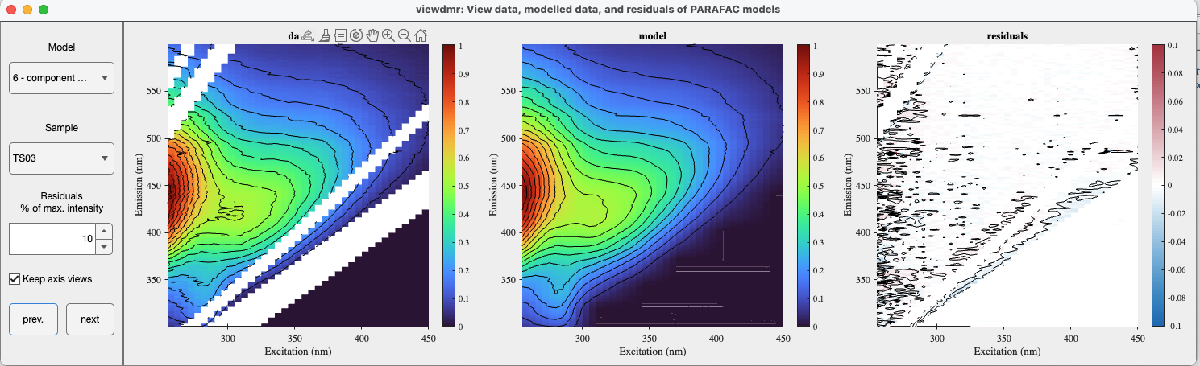

In the example above, the residuals reveal that some of the scatter was not cut. Particularly Rayleigh 2nd order (above and below), but also 1st order (above). Perhaps also some of the 1st order Raman (above and below), but to a lesser extent. Since the scatter removal was quite modest to begin with here, it might pay off to redo this and see if it helps with the loadings. Why?

***Scatter violates the model assumptions***

Non-trilinear data in your EEMs can really throw a wrench in the PARAFAC engine. There's really no telling what it'll do and it's difficult to diagnose. But it's the analyst's job to spot and attempt to fix it.

newSamples=samples;
tbx.viewscatter(newSamples)

Old options detected. These will be transfered to the GUI


viewscatter remembers the settings, so you don't start from scratch. You can just refine the settings and save them again to the workspace. I chose some settings and saved them to the workspace, then to the disk. Let's load them and apply them:

load("scatterSettings_refined.mat")
newSamples=tbx.handlescatter(newSamples,scatteroptions);
newSamples=tbx.addcomment(newSamples,'Created separate dataset to refine the scatter removal.');

With that done, it's time to repeat the PARAFAC runs and see if it changed anything. We'll go straight to the `viewdmr` app, but you might also want to inspect the model with `viewmodels`.

newSamples=tbx.fitparafac(newSamples, ...
    f=2:7, ...
    convergence=1e-8, ...
    starts=50, ...
    maxIteration=5000);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6  7]
Number of random starts:         50
Convergence criterion:           1e-08
Maximum number of iterations:    5000
Constraint:                      nonnegativity
% missing numbers:               16.442
-----
  
# 001 done | #iter: 293  | time: 00:02 | it/sec: 236
# 002 done | #iter: 310  | time: 00:02 | it/sec: 264
# 003 done | #iter: 258  | time: 00:02 | it/sec: 249
# 004 done | #iter: 293  | time: 00:02 | it/sec: 267
# 005 done | #iter: 251  | time: 00:01 | it/sec: 260
# 006 done | #iter: 293  | time: 00:02 | it/sec: 272
# 007 done | #iter: 280  | time: 00:01 | it/sec: 290
# 008 done | #iter: 293  | time: 00:02 | it/sec: 277
# 009 done | #iter: 223  | time: 00:01 | it/sec: 233
# 010 done | #iter: 243  | time: 00:02 | it/sec: 241
# 011 done | #iter: 258  | time: 00:02 | it/sec: 239
# 012 done |

%tbx.viewmodels(newSamples)
tbx.viewdmr(newSamples)
newSamples=tbx.addcomment(newSamples,'Residuals look more random');

A this stage, the residuals look very random for most of these samples. A quick look at the models actually also reveals that the loadings improved for the excitation, but not for the emission.

tbx.viewmodels(newSamples)
newSamples=tbx.addcomment(newSamples,'Ready for an attempt at model validation.');

Good and bad news, let's attept a model validation.

## Splitvalidation

newSamples=tbx.splitdataset(newSamples);

The default call to splitdataset performs a split into two datasets via an alternating assignment into split 1 or two. Here, we have very view samples and assigning the splits in this way also doesn't bias our split datasets in any way. However, this might not be the case in your dataset. 

***The validation is ******your****** safety check and you should perform it in a way that critically inspects your analysis. Have a look at the ***[***documentation***](matlab:open('splitdataset.html'))*** here.***

Next, we use the same function from before, but by specifiying `mode='split'`. This way, the function looks only at the split datasets, not the overall, original dataset. Though those models are still saved in the dataset as well.

newSamples=tbx.fitparafac(newSamples, ...
    mode='split', ...
    f=4:6,convergence=1e-8, ...
    starts=50);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [4  5  6]
Number of random starts:         50
Convergence criterion:           1e-08
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               16.442
-----
  
# 001 done | #iter: 1152 | time: 00:02 | it/sec: 617
# 002 done | #iter: 1171 | time: 00:02 | it/sec: 604
# 003 done | #iter: 1106 | time: 00:02 | it/sec: 625
# 004 done | #iter: 670  | time: 00:02 | it/sec: 540
# 005 done | #iter: 1741 | time: 00:03 | it/sec: 675
# 006 done | #iter: 706  | time: 00:02 | it/sec: 577
# 007 done | #iter: 1070 | time: 00:02 | it/sec: 629
# 008 done | #iter: 1097 | time: 00:02 | it/sec: 622
# 009 done | #iter: 872  | time: 00:02 | it/sec: 578
# 010 done | #iter: 868  | time: 00:02 | it/sec: 579
# 011 done | #iter: 1491 | time: 00:03 | it/sec: 656
# 012 done | #iter: 1

You can see from the final console output that the function also already performs spectral comparisons to let you know if the validation worked. The next call really only serves as visual output for ourselves.

newSamples=tbx.splitvalidation(newSamples,5);

 
Overall Result= Validated for all comparisons


% newSamples=tbx.splitvalidation(newSamples,6); Run to inspect

So... the five component model validated, but the six-component model looks quite chaotic. It's not just a minor issue, but something to investigate in detail. How did that five component model look? Let's start with the residuals again and then look at the loadings.

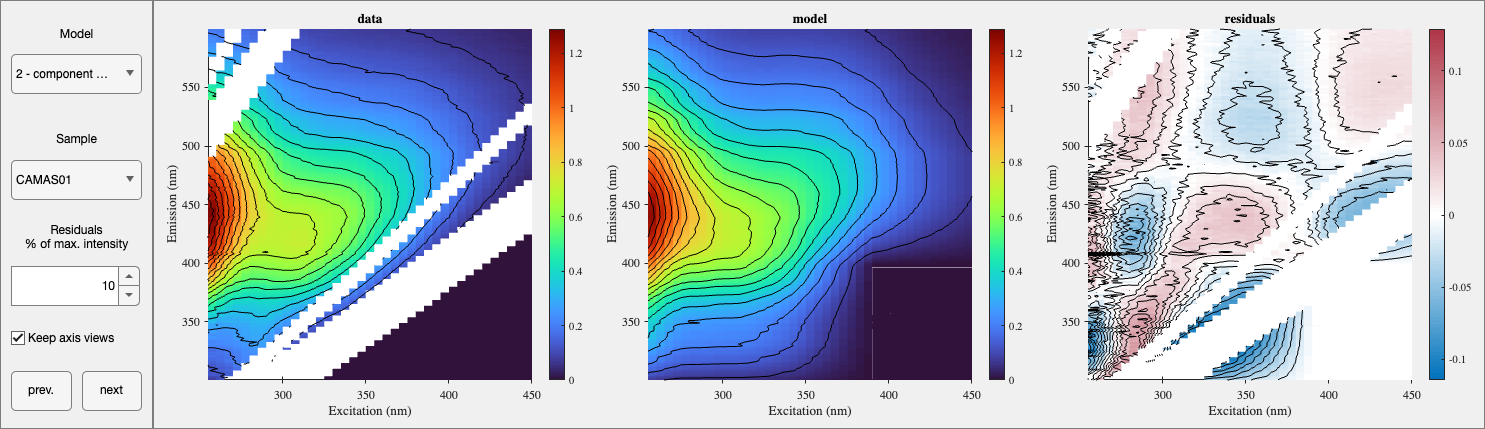

tbx.viewdmr(newSamples)

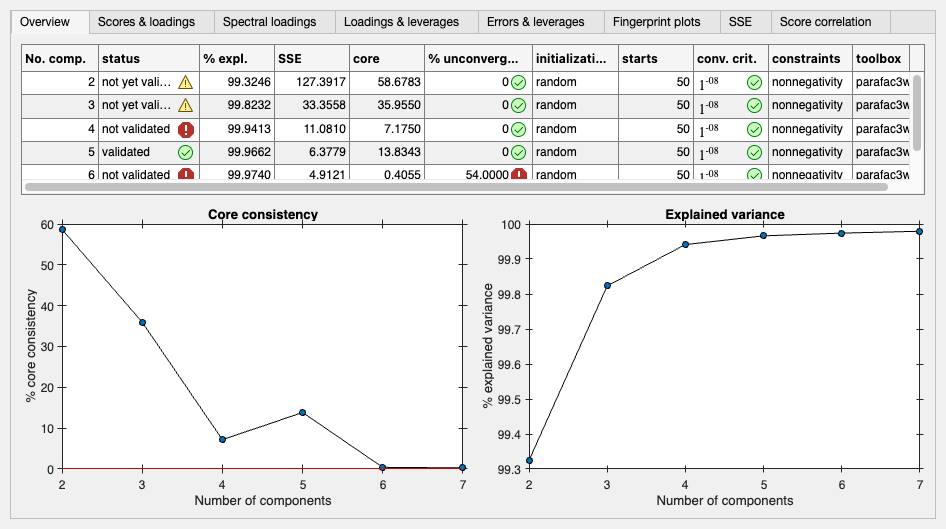

tbx.viewmodels(newSamples)

There are some systematic residuals, particularly for the first couple of samples. The loadings are not ideal either: A double emission peak and excitation loadings that hit zeros. But here, we only have 29 samples that mostly came from an estuarine salinity gradient. Not the most variable, but for sure very autocorrolated dataset. So it's not a surprise that PARAFAC is finding this job difficult. Let's save our hard work.

save('tutorial_parafac_modelled.mat',"samples","newSamples")

For the sake of this tutorial, we now move on to the next step. That's data export. Since it's a topic in itself, [you can find this in the Data export tutorial](matlab:open('./tutorial_export_01.html')).